%%%此文件可以得到旋转后平面和抛物面的方程以及图像
%%%运行改文件前需要先运行计算p的文件（optimal_r_rho),以及计算平面参数的文件（rotate_of_plat)
syms x y;
figure
alpha = deg2rad(36.795);
beta = deg2rad(78.169);
% beta = deg2rad(15)
R = 300;
rr = 150;
F = 0.466;
r1 = (1-F)*R;
theta = beta - pi/2;
z = (x^2 + y^2)/(2*p) - r1 - p/2;
vertex =[0;0; -r1-p/2];
% fsurf(z)
point = [x;y;z];
% u = [cos(beta)*sin(alpha) -cos(beta)*cos(alpha)];
u = [sin(alpha) -cos(alpha)];
K = [0, 0, u(2); 0, 0, -u(1); -u(2), u(1), 0];

% 计算旋转矩阵R
Rt = eye(3) + sin(theta) * K + (1 - cos(theta)) * (K^2);

% 计算旋转后的点
P_rot = Rt * point;
disp("选转后的顶点坐标")

选择后的顶点坐标


vertex_rot = (Rt*vertex)'

vertex_rot =   -49.3897  -36.9415 -294.4337



hold on
% fsurf(x_t,y_t,z_t);
%绘制抛物面
fsurf(P_rot(1),P_rot(2),P_rot(3),[-200 130 -200 130]);

%计算平面参数
z_plat_raw = rr^2/(2*p) - r1 - p/2;
point = [0 0 z_plat_raw];
n_plat = [cos(beta)*cos(alpha) cos(beta)*sin(alpha) sin(beta)];
u = [cos(beta)*sin(alpha) -cos(beta)*cos(alpha)]

u =     0.1228   -0.1642


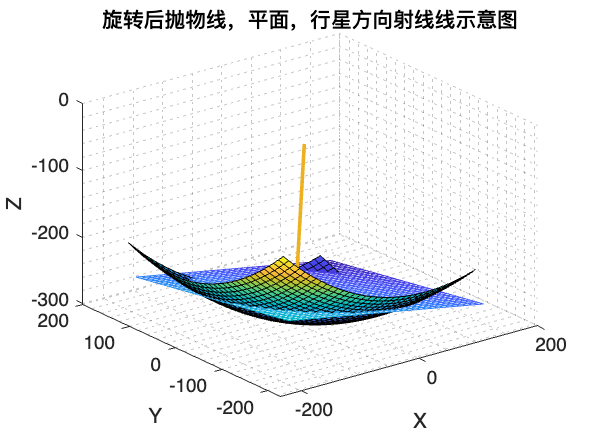

p_rot_plat = rotatePoint(point,u,theta);
f = @(x_plat, y_plat) (-n_plat(1)*(x_plat - p_rot_plat(1)) - n_plat(2)*(y_plat - p_rot_plat(2)))/n_plat(3) + p_rot_plat(3);
% 绘制平面
fmesh(f, [-200 130 -200 130]);

%绘制直线
syms t;
% scatter(p_rot_plat(1),p_rot_plat(2),p_rot_plat(3))
point_line = n_plat*t-p_rot_plat;
fplot3(point_line(1),point_line(2),point_line(3),[-500 -300],'LineWidth',2)
xlabel('X')
ylabel('Y')
zlabel('Z')
title('旋转后抛物线，平面，行星方向射线线示意图')
view(3);
grid minor
hold off